% EM Solver and IEM Solver

A = [0 -1;1 0]

A =      0    -1
     1     0


Z0 = [1; 0];
T = 10;
N = 20;

[x,y] = EMsolver(A,Z0(1),Z0(2),T,N)

x =     1.0000    1.0000    0.7500    0.2500   -0.4375   -1.1875   -1.8281   -2.1719   -2.0586   -1.4023   -0.2314    1.2900    2.8694    4.1262    4.6657    4.1736    2.5152   -0.1868   -3.5174   -6.8014   -9.2061


y =          0    0.5000    1.0000    1.3750    1.5000    1.2812    0.6875   -0.2266   -1.3125   -2.3418   -3.0430   -3.1587   -2.5137   -1.0790    0.9841    3.3170    5.4038    6.6614    6.5680    4.8093    1.4086


[x1, y1] = IEMsolver(A, Z0(1),Z0(2), T, N)

x1 =     1.0000    0.8750    0.5156    0.0137   -0.4998   -0.8885   -1.0472   -0.9303   -0.5645   -0.0430    0.4981    0.9153    1.0959    0.9882    0.6164    0.0750   -0.4948   -0.9420   -1.1461   -1.0488   -0.6715


y1 =          0    0.5000    0.8750    1.0234    0.9023    0.5397    0.0280   -0.4991   -0.9019   -1.0714   -0.9590   -0.5900   -0.0586    0.4967    0.9287    1.1208    1.0182    0.6435    0.0921   -0.4925   -0.9553


[x2, y2] = IEMsolver_clarity(A, Z0(1),Z0(2), T, N)

x2 =     1.0000    0.8750    0.5156    0.0137   -0.4998   -0.8885   -1.0472   -0.9303   -0.5645   -0.0430    0.4981    0.9153    1.0959    0.9882    0.6164    0.0750   -0.4948   -0.9420   -1.1461   -1.0488   -0.6715


y2 =          0    0.5000    0.8750    1.0234    0.9023    0.5397    0.0280   -0.4991   -0.9019   -1.0714   -0.9590   -0.5900   -0.0586    0.4967    0.9287    1.1208    1.0182    0.6435    0.0921   -0.4925   -0.9553


t = 0:(T/N):T

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


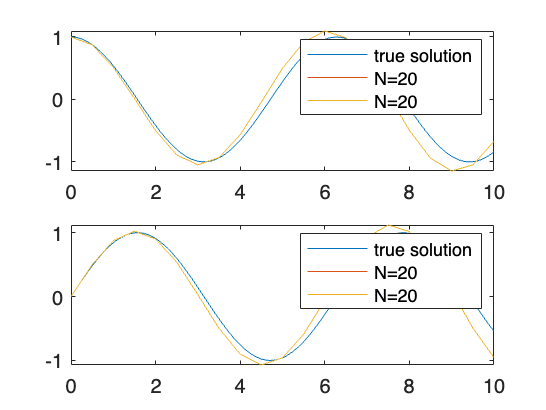


t_plot = 0:0.1:T;
cos_plot = cos(t_plot);
sin_plot = sin(t_plot);
figure
subplot(2,1,1)
plot(t_plot,cos_plot,"DisplayName","true solution")
hold on
plot(t,x1,"DisplayName","N="+num2str(N))
hold on
plot(t,x2,"DisplayName","N="+num2str(N))
legend()
subplot(2,1,2)
plot(t_plot,sin_plot,"DisplayName","true solution")
hold on
plot(t,y1,"DisplayName","N="+num2str(N))
hold on
plot(t,y2,"DisplayName","N="+num2str(N))
legend()

function [x,y] = EMsolver(A,x_0,y_0,T,N)
 
    dt = T/N;
    t = 0:dt:T;
     
    SOL = NaN(2,length(t));
    SOL(1,1) = x_0;
    SOL(2,1) = y_0;
     
    for k = 2:length(t)
        SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
    end
    x = SOL(1,:);
    y = SOL(2,:);
end

function [x, y] = IEMsolver(A, x_0, y_0, T, N)
    dt = T/N;
    t = 0:dt:T;

%     [x, y] = EMsolver(A,x_0,y_0,T,N);
%     SOL = [x; y];
% no!!! this is wrong. should not be using entire slope estimates from EM
    SOL = NaN(2, length(t));
    SOL(1,1) = x_0;
    SOL(2,1) = y_0;
    for k = 2:length(t)
        SOL(:,k) = SOL(:,k-1) + dt*(A*SOL(:,k-1)+A*(SOL(:,k-1)+dt*A*SOL(:,k-1)))/2;
    end
    x = SOL(1,:);
    y = SOL(2,:);
end

function [x, y] = IEMsolver_clarity(A, x_0, y_0, T, N)
    dt = T/N;
    t = 0:dt:T;
    % makes timestep

    SOL = NaN(2, length(t));
    SOL(1, 1) = x_0;
    SOL(2, 1) = y_0;

    % initialize vector that contains the solution

    for k = 2:length(t)
        % left slope is just Z(n) = AZ(n-1)
        SL = A*SOL(:,k-1);
        % right slope is AZ(n) = A(Z(n) + tAZ(n))
        % this is EM method of right slope
        SR = A*(SOL(:,k-1) + dt*A*SOL(:,k-1));
        % average slope
        S = (SL+SR)/2;
        % final solution Z(n) = Z(n-1) + t/2(left slope+right slope)
        SOL(:,k) = SOL(:, k-1)+dt*S;
    end
    x = SOL(1, :);
    y = SOL(2, :);

end